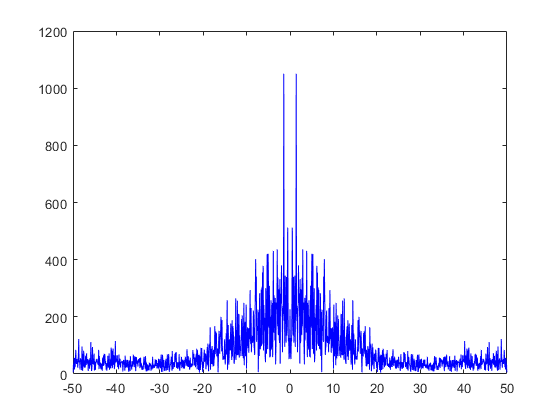

clf
clear all


data_1 = xlsread('form_2_foot_start.xls'); %Just select the file
[set_1,set_2,set_3] = split_data(data_1);

frequency_domain(set_3) %Select the set from set_1 to set_3

function [M_1,M_2,M_3] = split_data(data)
    time = data(:,1);
    x = data(:,2);
    y = data(:,3);
    z = data(:,4);
    absolute = data(:,5);
    
    data_size = size(time, 1);
    x_1 = x(1:(round(data_size/3)));
    x_2 = x(round((data_size/3)):(round((data_size/3))*2));
    x_3 = x((round((data_size/3))*2):(round((data_size/3))*3));
%     x_4 = x((round((data_size/3))*3):(round((data_size/3))*4));
%     x_5 = x((round((data_size/3))*4):data_size);
    time_1 = time(1:(round(data_size/3)));
    time_2 = time(round((data_size/3)):(round((data_size/3))*2));
    time_3 = time((round((data_size/3))*2):(round((data_size/3))*3));
%     time_4 = time((round((data_size/3))*3):(round((data_size/3))*4));
%     time_5 = time((round((data_size/3))*4):data_size);
    
    M_1 = [time_1, x_1];
    M_2 = [time_2, x_2];
    M_3 = [time_3, x_3];
%     M_4 = [time_4, x_4];
%     M_5 = [time_5, x_5];
    
end

function [] = frequency_domain(data)
    x = data(:,2);
    time = data(:,1);
    
    nFoot = size(x,1);
    Fs = 100;
    f = linspace(-Fs/2, Fs/2 - Fs/nFoot, nFoot) + Fs/(2*nFoot)*mod(nFoot, 2);
    FOOTXONE = fft(x);

    clf
    plot(f,fftshift(abs(FOOTXONE)),'b');

    spectrum = fftshift(abs(FOOTXONE));
    freqs_hz = f;
    filter_val = 2;
    filter_inds = -1 * filter_val <=abs(f) & abs(f) >= filter_val; 
    spectrum_filt = spectrum;
    spectrum_filt(filter_inds) = spectrum_filt(filter_inds)/10;
end